## 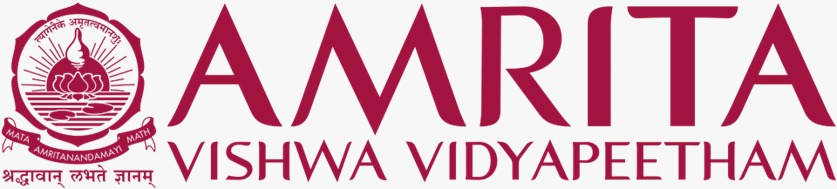

## **22MAT230 MATHEMATICS FOR COMPUTING 4**

## **Batch : AIE -C**

### **Team C-11**

- **Jovika N B                       -  CB.SC.U4AIE24223**

- ** P Poojitha            -  CB.SC.U4AIE24237**

- **Ramu Jahna Bindu        - CB.SC.U4AIE24249 **

- **Potnuru Varun                - CB.SC.U4AIE24244**

clc;clearvars;close all;tic
rng(42);
Dataset_root="C:\Users\pooji\OneDrive\Desktop\MFC4\EuroSAT";
Dataset_path=Dataset_root;
Classes = {'Highway','Residential','Forest','SeaLake','River'};
Num_clusters=5;
Images_per_class=400;

If 0 zeros appers while printing then mismatch of class

`fullfile()` is a inbuilt matlab function that **joins folder names safely**

for i =1:length(Classes)
    folder=fullfile(Dataset_path,Classes{i});
    disp(isfolder(folder));
end

   1

   1

   1

   1

   1



this for loop used for whether the class is correctly selected or mismatched

#### Load Image paths

imds=imageDatastore(Dataset_path,...
    'IncludeSubfolders',true,...
    'LabelSource','foldernames');
imds=subset(imds,ismember(imds.Labels,Classes));
imds.Labels=removecats(imds.Labels);
imds=splitEachLabel(imds,Images_per_class,'randomized');
disp("Total images loaded:")

Total images loaded:


disp(numel(imds.Files))

        2000



countEachLabel(imds)

ans = 5×2 table
       Label       Count
    ___________    _____

    Forest          400 
    Highway         400 
    Residential     400 
    River           400 
    SeaLake         400 


labels=grp2idx(imds.Labels);
disp(unique(labels))

     1
     2
     3
     4
     5



Deep Feature Extraction(Using Resnet -50)

net=resnet50;
inputSize = net.Layers(1).InputSize(1:2)%ResNet takes input of 224×224 RGB images

inputSize =    224   224


augimds = augmentedImageDatastore(inputSize, imds);

- Resizes all images to 224×224

- Feeds them batch-by-batch

- Keeps memory usage controlled

Extract Deep Features using gpu

features=activations(net,augimds,'avg_pool',...
    'MiniBatchSize',32,...
    'ExecutionEnvironment','gpu');

here  features = 1×1×2048×2000 single array


$$\text{features} \in \mathbb{R}^{1 \times 1 \times 2048 \times 2000}
$$


#  Why 2048?

Because we extracted from:

`'avg_pool'`

In **ResNet-50**, the final global average pooling layer outputs:

                                                                            
$$
2048 \text{ deep features per image}
$$


Each of those numbers is a high-level learned feature like:

- water texture

- forest density

- urban pattern

- road structure

- coastline boundaries

we  are NOT seeing pixel values.

we are seeing **deep neural embeddings**.

Right now the shape is $1$x$1$x$2000$x$2048$

so for performing kmeans  we need convert it to  $2000$ x $2048$.

features=squeeze(features);%removes 1x1
X=gather(features)';% transpose to N × 2048
size(X)

ans =         2000        2048


One image → 2048 numbers

Those 2048 numbers are:

High-level features learned from ImageNet:

- texture

- edges

- shape

- patterns

- land structure

- water boundaries

- urban patterns

This is why we use deep features instead of raw pixels.


% COVARIANCE MATRIX OF FEATURES
cov_matrix = cov(X);
disp("Covariance matrix size:")

Covariance matrix size:


disp(size(cov_matrix))

        2048        2048



OUT_DIR='D:/EuroSAT_Outputs';
if ~isfolder(OUT_DIR)
    mkdir(OUT_DIR);
end
disp(isfolder(OUT_DIR))

   1



save(fullfile(OUT_DIR,'embeddings.mat'),'X');

Num_clusters=5;
[idx_km,C]=kmeans(X,Num_clusters,...
    'Replicates',10,...
    'MaxIter',1000);
tabulate(idx_km)

  Value    Count   Percent
      1      360     18.00%
      2      409     20.45%
      3      428     21.40%
      4      421     21.05%
      5      382     19.10%


k_means=clustering_accuracy(labels,idx_km)

k_means = 0.8570

disp(k_means)

    0.8570



# What Is 0.8570?

It is **Clustering Accuracy (ACC)**.

Mathematically:

                        
$$\text{ACC} = \frac{\text{Correctly matched samples}}{\text{Total samples}}$$


We have:

- 2000 total images

- 5 true classes

- 5 clusters from KMeans

And the function computed $ACC$:0.8570

Which means:

                        
$$0.8645 \times 2000 = 1714\text{ images approximately}$$


# Clustering Accuracy (ACC)

Clustering accuracy measures **how many samples are correctly assigned to their true classes after optimal mapping between clusters and labels**.

Because clustering labels are arbitrary, we first find the **best permutation (mapping)** between cluster IDs and ground-truth labels.

**Formula :**

                $ACC$ = $\frac{1}{N} \sum_{i=1}^{N} \delta \left(y_i , map(c_i)\right)$

Where

- $N$ = total number of samples

- $y_i$ = true label of sample $i$

- $c_i$� = predicted cluster of sample $i$

- $map()$ = optimal mapping between clusters and labels

- $\delta$ = indicator function

Indicator function:

                            $\delta(a,b)$= $\begin{cases} 1 & a=b \\ 0 & a\neq b \end{cases}$

ACC = 1 → perfect clustering

ACC = 0 → completely incorrect clustering

�Function for  Calculating Cluster Accuracy

function acc = clustering_accuracy(y_true, y_pred)


ans =         2000        2000


    y_true = y_true(:);
    y_pred = y_pred(:);

    cm = confusionmat(y_true, y_pred);


sigma = single
33.3014

    correct = sum(max(cm, [], 2));
    acc = correct / length(y_true);

end

# Normalized Mutual Information (NMI)

NMI measures **how much information the predicted clusters share with the true labels**.

It is based on **mutual information from information theory**.

**Formula:**

                $NMI(Y,C)$ = $\frac{I(Y,C)} {\sqrt{H(Y)H(C)}}$�

Where

- $Y$ = ground truth labels

- $C$= predicted clusters

**Mutual Information:**

                 $I(Y,C)$ = $\sum_{y \in Y} \sum_{c \in C} p(y,c) \log \frac{p(y,c)}{p(y)p(c)}$

Where

- $p(y,c)$ = joint probability

- $p(y)$ = probability of class

- $p(c)$ = probability of cluster

**Entropy:**

                 $H(Y)$ = $-\sum_{y} p(y)\log p(y)$   

                $H(C)$ = $-\sum_{c} p(c)\log p(c)$

#### Range:

                
$$0 \le  NMI \le  1$$


$0$ → clusters independent of labels

$1$ → perfect clustering

Function for Calculating NMI(Normalized Mutual information)

function score = nmi(y_true, y_pred)

    y_true = y_true(:);
    y_pred = y_pred(:);
    N = length(y_true);

    cm = confusionmat(y_true, y_pred);
    ni = sum(cm,2);
    nj = sum(cm,1);

    MI = 0;
    for i = 1:size(cm,1)
        for j = 1:size(cm,2)
            if cm(i,j) > 0

ans =         2000        2000


                MI = MI + (cm(i,j)/N) * ...

                     log((N*cm(i,j)) / (ni(i)*nj(j)));

ans =         2000           5


            end
        end
    end

    H_true = -sum((ni/N) .* log(ni/N));
    H_pred = -sum((nj/N) .* log(nj/N));


    0.8195



    score = MI / sqrt(H_true * H_pred);
end

# Adjusted Rand Index (ARI)

ARI evaluates clustering based on **pairwise sample agreements**.

It measures how many **pairs of samples are grouped correctly**.

**First compute Rand Index:**

                $RI$ = $\frac{TP + TN} {TP + FP + FN + TN}$�

Where

- $TP$ = pairs in same cluster and same class

- $TN$ = pairs in different clusters and different classes

- $FP$ = pairs in same cluster but different class

- $FN$ = pairs in different clusters but same class

#### Adjusted Rand Index:

                $ARI$=$$\frac{RI-Expected(RI)} {Max(RI)-Expected(RI)}$$

#### Range:

              $ARI=1\to$perfect clustering

             $
              ARI = 0 \to  $random clustering

            $              ARI < 0\to  $worse than random�

Function for Calculating ARI(Adjusted Rand Index)

function score = ari_score(y_true, y_pred)

    y_true = y_true(:);
    y_pred = y_pred(:);

    N = length(y_true);
    cm = confusionmat(y_true, y_pred);

    sum_comb_c = sum(nchoosek_vector(sum(cm,2)));
    sum_comb_k = sum(nchoosek_vector(sum(cm,1)));
    sum_comb = sum(nchoosek_vector(cm(:)));

    total_comb = nchoosek(N,2);

    expected_index = (sum_comb_c * sum_comb_k) / total_comb;
    max_index = 0.5 * (sum_comb_c + sum_comb_k);

    score = (sum_comb - expected_index) / ...
            (max_index - expected_index);
end

function s = nchoosek_vector(v)
    s = v .* (v - 1) / 2;
end

#### Spectral Clustering (Global Sigma)

D=pdist2(X,X);
size(D)

Properties of D

- Diagonal = 0(distance from image to itself)

- Symmetric   :    $D_{ij}=D_{ji}$

norm(D-D');%beacuse of the properties of D norm will be equal to zero
sortedD=sort(D,2);
sigma=median(sortedD(:,2:end),'all')

                
$$D_{ij}=\parallel x_i-x_j\parallel $$


 Sort each row independently

 From smallest distance to largest

sortedD(:,2:end)  → removes self-distances

# What Does Sigma Represent?

Sigma is a **scale parameter**.

It controls how fast similarity decays.

In the Gaussian kernel:

                                    
$$W_{ij} = e^{-\frac{\|x_i - x_j\|^2}{2\sigma^2}}
$$
 

# Why Use Median?

We could use:

- mean

- fixed constant

- nearest neighbor distance

But median is robust because:

- It ignores extreme outliers

- It captures typical dataset scale

If sigma is:

Too small → graph becomes disconnected

Too large → everything looks similar

Using median gives balanced connectivity

### Affinity Matrix

W=exp(-(D.^2)/(2*sigma^2));
W(1:size(W,1)+1:end)=0;
min(W(:));
max(W(:));

# Important Concept

Unlike KMeans (which uses distances directly),

Spectral clustering works on:

1.Graph connectivity

2.Local neighborhoods

3.Manifold structure

So now our dataset is represented as a weighted graph.

Dg=diag(sum(W,2));
L=eye(size(W))-Dg^(-1/2)*W*Dg^(-1/2);%Normalized Laplacian
size(L)
[U, ~] = eigs(L, Num_clusters, 'smallestabs');
size(U)

U = U ./ vecnorm(U,2,2);
idx_spec = kmeans(U, Num_clusters, ...
    'Replicates', 10, ...
    'MaxIter', 1000);
Global_sigma=clustering_accuracy(labels, idx_spec);
disp(Global_sigma)

    0.9020



## Self Tuning

Earlier (Global Sigma):

                                          
$$W_{ij} = e^{-\frac{\|x_i - x_j\|^2}{2\sigma^2}}
$$


Now we use:

                                           
$$W_{ij} = e^{-\frac{\|x_i - x_j\|^2}{\sigma_i\sigma_j }{}
$$


Where:

                    $\sigma_i$ = $\text{k-th nearest neighbor distance of point }$

This adapts similarity locally.

 for each image $i$:

                    $\sigma_i$= $\text{distance to its 25th neighbor}$


k = 25;
N = size(X,1);

% pairwise distances
D = pdist2(X,X);

% sort distances
[sortedD, idx] = sort(D,2);

% local sigma = distance to k-th neighbor

----- FINAL METRICS -----


sigma_local = sortedD(:,k+1);

% squared distances
D2 = D.^2;

% sigma_i * sigma_j
sigma_matrix = sigma_local * sigma_local';

% affinity matrix using self-tuning kernel
W_self = exp(-D2 ./ (2*sigma_matrix));

---Final Metrics---


            Method              ACC        NMI        ARI  
    _______________________    ______    _______    _______

    "KMeans"                    0.857    0.75065     0.7162
    "Spectral Global Sigma"    0.8195    0.68705    0.64664
    "Spectral Self-Tuning"      0.902    0.79247    0.67596



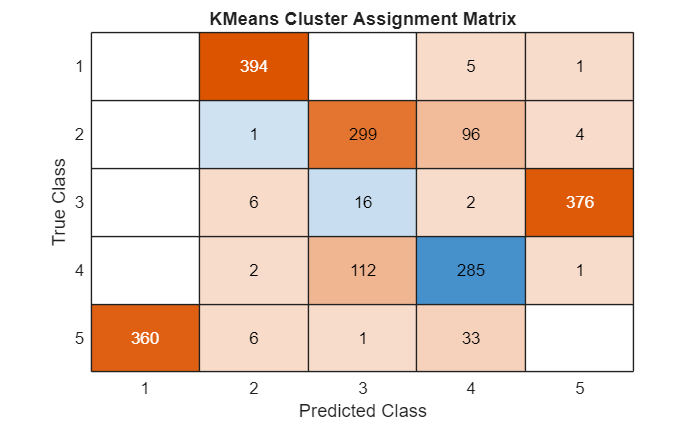

%to remove self loops
W_self = W_self - diag(diag(W_self));

% KEEP ONLY k NEAREST NEIGHBOURS


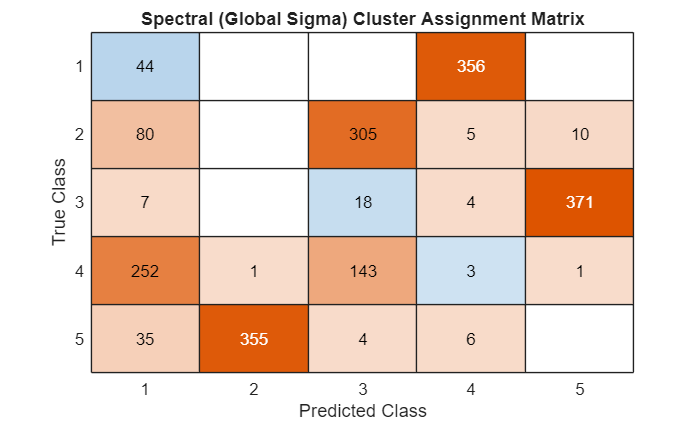

mask = false(N,N);

for i = 1:N
    mask(i, idx(i,2:k+1)) = true; % keep 25 neighbours

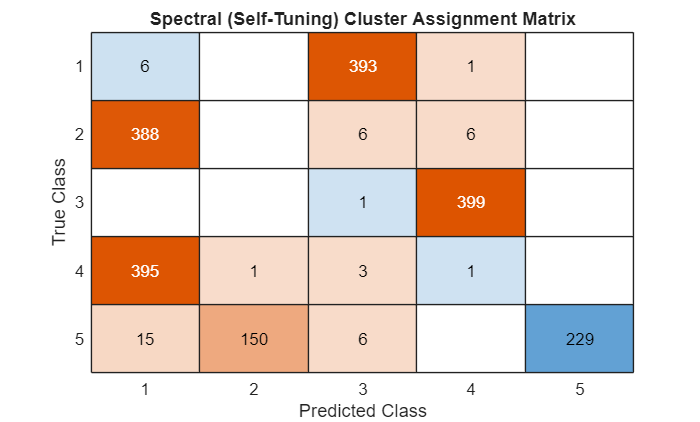

end

% apply mask
W_self(~mask) = 0;


% make graph symmetric
W_self = 0.5 * (W_self + W_self');

Dg_self=diag(sum(W_self,2));

L_self=eye(N)-Dg_self^(-1/2)*W_self*Dg_self^(-1/2);
[U_self, ~] = eigs(L_self, Num_clusters, 'smallestreal');

Variance explained by first 10 components:


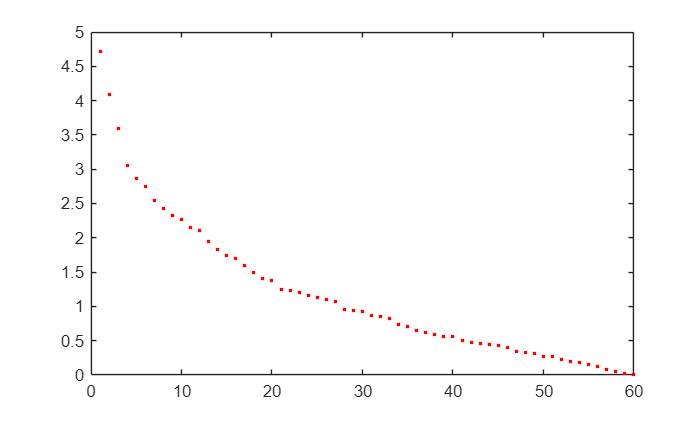

U_self = bsxfun(@rdivide, U_self, sqrt(sum(U_self.^2,2)) + 1e-10);

idx_self = kmeans(U_self, Num_clusters, ...

    'Replicates',10, ...

   20.3741
   10.8875
    6.6387
    3.8771
    3.2095
    2.8570
    2.3028
    2.0601
    1.8737
    1.7506



    'MaxIter',1000, ...
    'Start','plus');
Self_Tuning = clustering_accuracy(labels, idx_self);
disp(Self_Tuning)

Variance retained by first 2 components:


% --- NMI ---

   31.2616



nmi_km = nmi(labels, idx_km);
nmi_global = nmi(labels, idx_spec);
nmi_self = nmi(labels, idx_self);


Variance retained by first 3 components:


% --- ARI ---

   37.9003



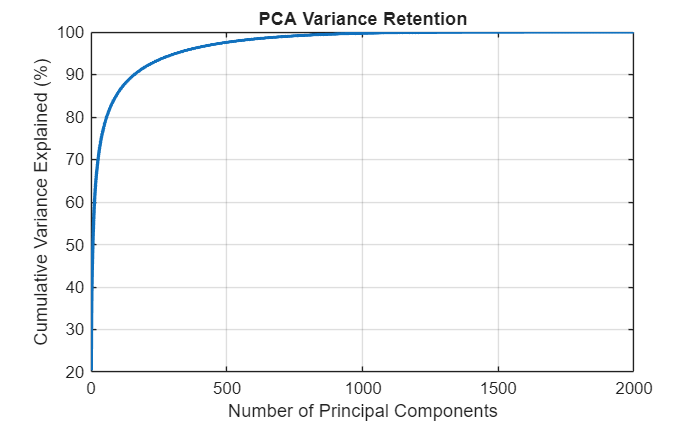

ari_km = ari_score(labels, idx_km);
ari_global = ari_score(labels, idx_spec);
ari_self = ari_score(labels, idx_self);

disp("----- FINAL METRICS -----")

Method = ["KMeans"; "Spectral Global Sigma"; "Spectral Self-Tuning"];

ACC = [k_means; Global_sigma; Self_Tuning];

NMI = [nmi_km; nmi_global; nmi_self];
ARI = [ari_km; ari_global; ari_self];

results_table = table(Method, ACC, NMI, ARI);

disp("---Final Metrics---")
disp(results_table)

 KMeans Confusion

figure;
cm_km=confusionchart(labels, idx_km);
title('KMeans Cluster Assignment Matrix');

Global Sigma

figure;
confusionchart(labels, idx_spec);
title('Spectral (Global Sigma) Cluster Assignment Matrix');

Self-Tuning

figure;
confusionchart(labels, idx_self);
title('Spectral (Self-Tuning) Cluster Assignment Matrix');

Cluster labels are arbitrary in unsupervised learning.

Therefore we aligned clusters with ground-truth classes using the confusion matrix before assigning class names.

#### PCA ANALYSIS

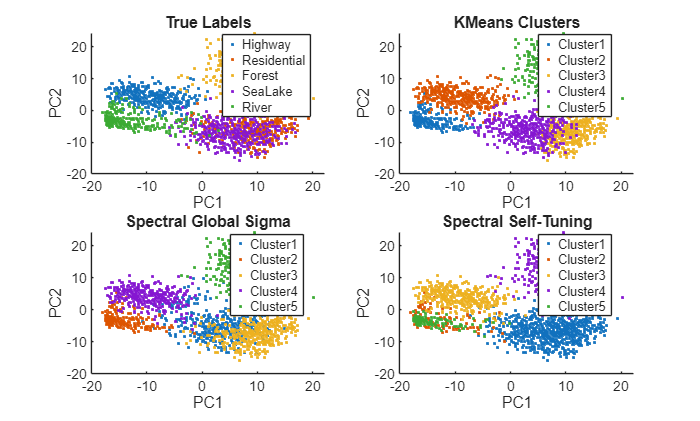


[coeff, score, latent, ~, explained] = pca(X);

disp("Variance explained by first 10 components:")
vsco = var(score);%variance of score
figure
plot(log(vsco(vsco>1)),"r.")
disp(explained(1:10))

% variance retained in 2D
variance_2D = sum(explained(1:2));
disp("Variance retained by first 2 components:")
disp(variance_2D)

% variance retained in 3D
variance_3D = sum(explained(1:3));
disp("Variance retained by first 3 components:")

disp(variance_3D)
class_names = {'Highway','Residential','Forest','SeaLake','River'};

#### PCA VARIANCE SPECTRUM

figure
plot(cumsum(explained),'LineWidth',2)
xlabel('Number of Principal Components')
ylabel('Cumulative Variance Explained (%)')
title('PCA Variance Retention')
grid on

#### PCA 2D VISUALIZATION

X_pca2 = score(:,1:2);

figure

subplot(2,2,1)
gscatter(X_pca2(:,1), X_pca2(:,2), labels)
title('True Labels')
xlabel('PC1')
ylabel('PC2')
legend(class_names,'Location','best')

subplot(2,2,2)
gscatter(X_pca2(:,1), X_pca2(:,2), idx_km)
title('KMeans Clusters')
xlabel('PC1')
ylabel('PC2')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5','Location','best')

subplot(2,2,3)
gscatter(X_pca2(:,1), X_pca2(:,2), idx_spec)
title('Spectral Global Sigma')
xlabel('PC1')
ylabel('PC2')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5','Location','best')

subplot(2,2,4)
gscatter(X_pca2(:,1), X_pca2(:,2), idx_self)
title('Spectral Self-Tuning')
xlabel('PC1')
ylabel('PC2')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5','Location','best')

#### PCA 3D VISUALIZATION 

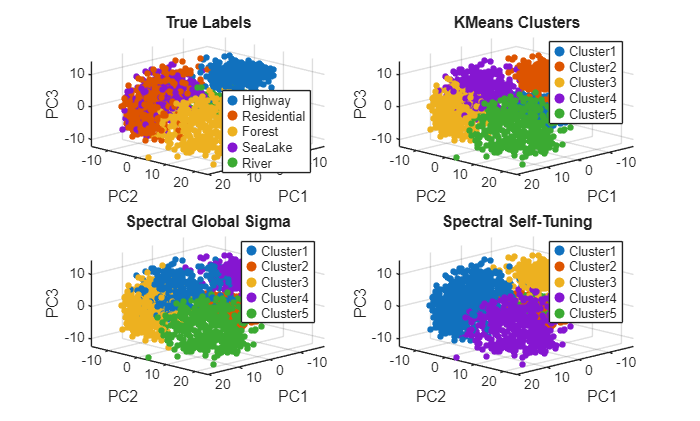

X_pca3 = score(:,1:3);

colors = lines(5);

figure

%TRUE LABELS
subplot(2,2,1)
hold on
for i = 1:5
    idx = labels == i;
    scatter3(X_pca3(idx,1),X_pca3(idx,2),X_pca3(idx,3),15,...
        colors(i,:),'filled')
end
title('True Labels')
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
legend(class_names,'Location','best')
grid on
view(135,25)
hold off


%KMEANS
subplot(2,2,2)
hold on
for i = 1:5
    idx = idx_km == i;
    scatter3(X_pca3(idx,1),X_pca3(idx,2),X_pca3(idx,3),15,...
        colors(i,:),'filled')
end
title('KMeans Clusters')
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5')
grid on

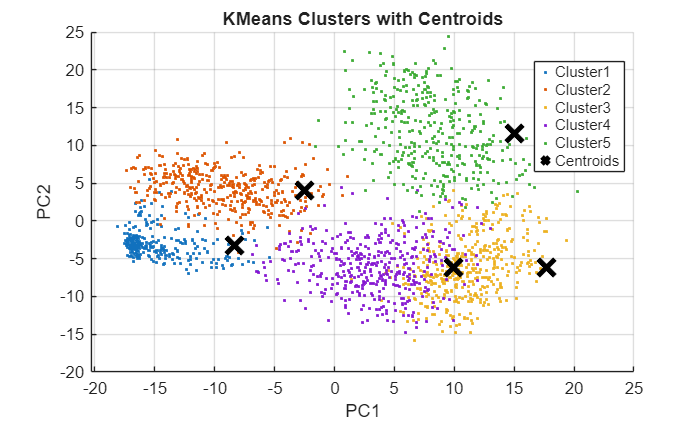

view(135,25)
hold off


% GLOBAL SIGMA
subplot(2,2,3)
hold on
for i = 1:5
    idx = idx_spec == i;
    scatter3(X_pca3(idx,1),X_pca3(idx,2),X_pca3(idx,3),15,...
        colors(i,:),'filled')
end
title('Spectral Global Sigma')
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5')
grid on
view(135,25)
hold off



% SELF TUNING
subplot(2,2,4)
hold on
for i = 1:5
    idx = idx_self == i;
    scatter3(X_pca3(idx,1),X_pca3(idx,2),X_pca3(idx,3),15,...
        colors(i,:),'filled')
end
title('Spectral Self-Tuning')
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5')
grid on
view(135,25)
hold off

####  KMEANS CENTROIDS VISUALIZATION(2D)

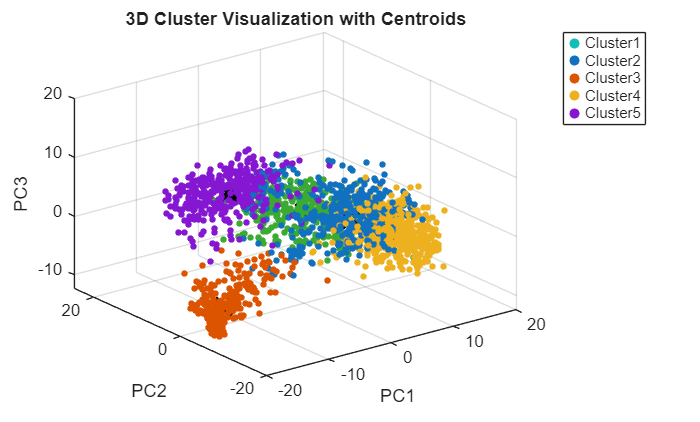


X_pca2 = score(:,1:2);

figure
gscatter(X_pca2(:,1), X_pca2(:,2), idx_km)
hold on

% Project centroids into PCA space
C_pca = C * coeff(:,1:2);

scatter(C_pca(:,1), C_pca(:,2), 200, 'k', 'x', 'LineWidth',3)

title("KMeans Clusters with Centroids")
xlabel("PC1")
ylabel("PC2")

legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5','Centroids')
grid on

#### 3D CENTROID VISUALIZATION

X_pca3 = score(:,1:3);

Elapsed time is 31.050886 seconds.



figure

scatter3(X_pca3(:,1),X_pca3(:,2),X_pca3(:,3),15,idx_km,'filled')
hold on

% Compute centroids in PCA space
centroids = zeros(Num_clusters,3);



for i = 1:5
    idx = idx_spec == i;
    scatter3(X_pca3(idx,1),X_pca3(idx,2),X_pca3(idx,3),15,...
        colors(i,:),'filled')
end
for i = 1:Num_clusters
    centroids(i,:) = mean(X_pca3(idx_km==i,:),1);
end

scatter3(centroids(:,1),centroids(:,2),centroids(:,3),...
         200,'k','x','LineWidth',3)
legend('Cluster1','Cluster2','Cluster3','Cluster4','Cluster5')

xlabel('PC1')
ylabel('PC2')
zlabel('PC3')

title('3D Cluster Visualization with Centroids')


grid on
rotate3d on

toc